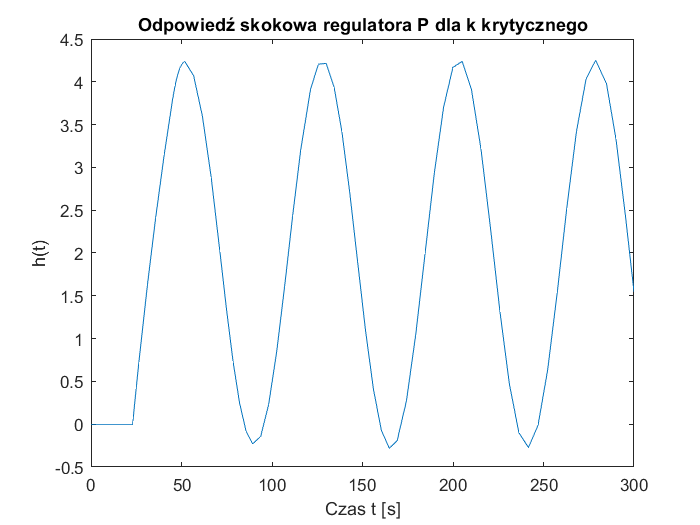

k = 1.18;
tau = 22;
T = 45;

kreg = 3.32;
Ti = 0;
Td = 0;
out = sim('model.slx');
plot(out.y.time, out.y.signals.values)
title("Odpowiedź skokowa regulatora P dla k krytycznego")
xlabel("Czas t [s]")
ylabel("h(t)")

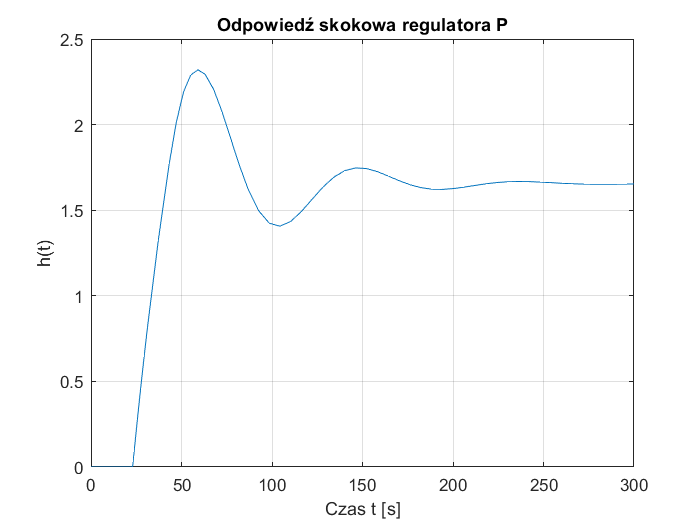

%[czas,y]=ginput(2)
%Tosc = czas(2) - czas(1)

kkryt = 3.32;
Tosc = 76.6129;

kreg = 0.5 * kkryt;
Ti = 0;
Td = 0;
out = sim("model.slx");
plot(out.y.time, out.y.signals.values)
title("Odpowiedź skokowa regulatora P")
xlabel("Czas t [s]")
ylabel("h(t)")
grid on

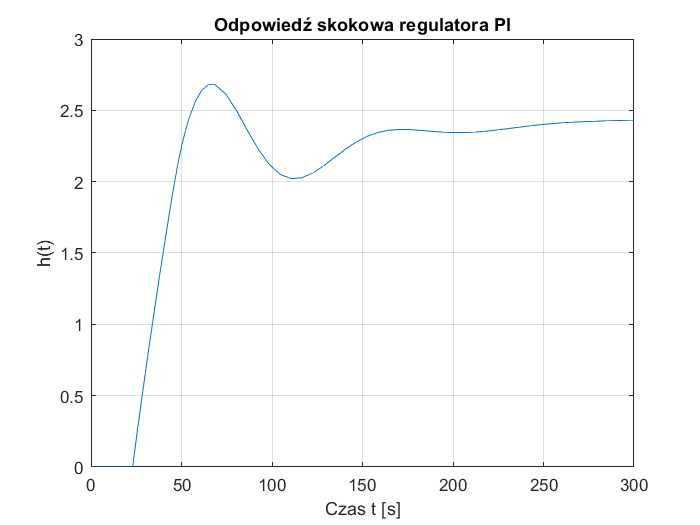


kreg = 0.45 * kkryt;
Ti = 1/(0.85 * Tosc);
Td = 0;
out = sim("model.slx");
plot(out.y.time, out.y.signals.values)
title("Odpowiedź skokowa regulatora PI")
xlabel("Czas t [s]")
ylabel("h(t)")
grid on

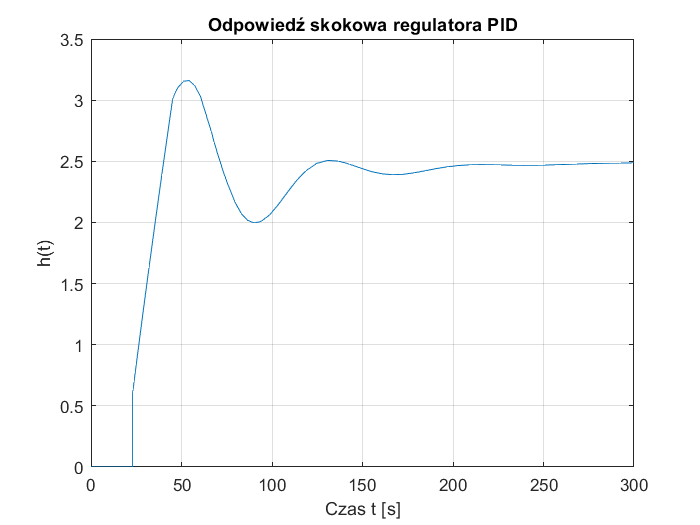


kreg = 0.6 * kkryt;
Ti = 1/(0.5 * Tosc);
Td = 0.12 * Tosc;
out = sim("model.slx");
plot(out.y.time, out.y.signals.values)
title("Odpowiedź skokowa regulatora PID")
xlabel("Czas t [s]")
ylabel("h(t)")
grid on

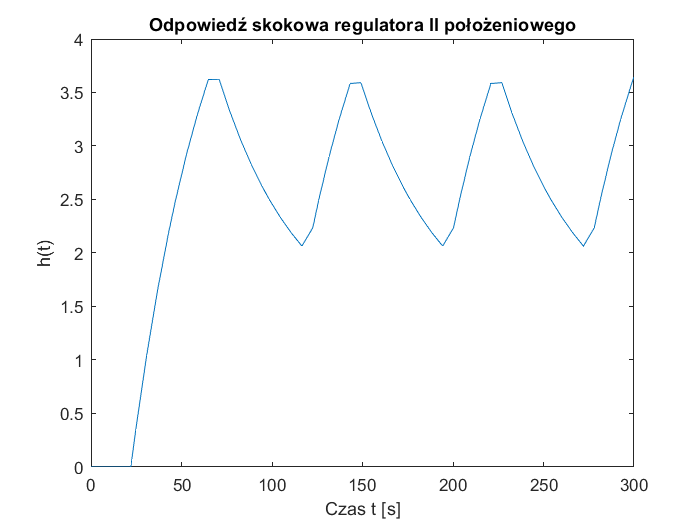

k = 1.18;
tau = 22;
T = 45;
out = sim('model2.slx');
plot(out.y.time, out.y.signals.values)
title("Odpowiedź skokowa regulatora II położeniowego")
xlabel("Czas t [s]")
ylabel("h(t)")

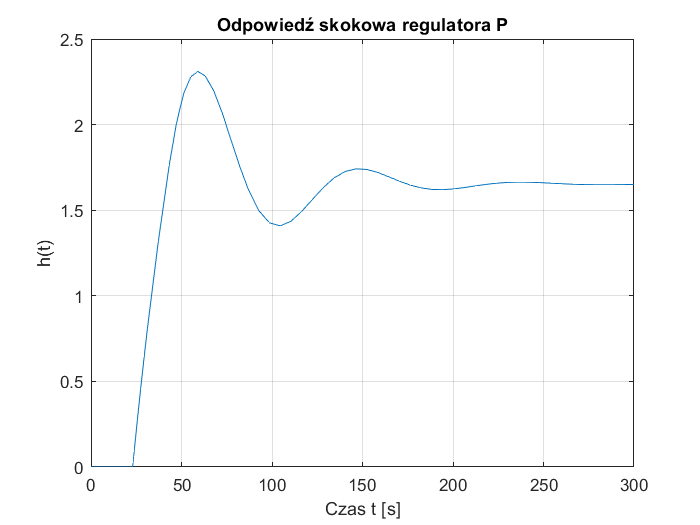

% [czas,y]=ginput(2)
% Tosc = czas(2) - czas(1)
% [czas,y]=ginput(2)
% A = (y(2) - y(1))/2
A = 0.771;
Tosc = 78.43;
u = 2;
kkryt = (4 * u)/(pi * A);

kreg = 0.5 * kkryt;
Ti = 0;
Td = 0;
out = sim("model.slx");
plot(out.y.time, out.y.signals.values)
title("Odpowiedź skokowa regulatora P")
xlabel("Czas t [s]")
ylabel("h(t)")
grid on

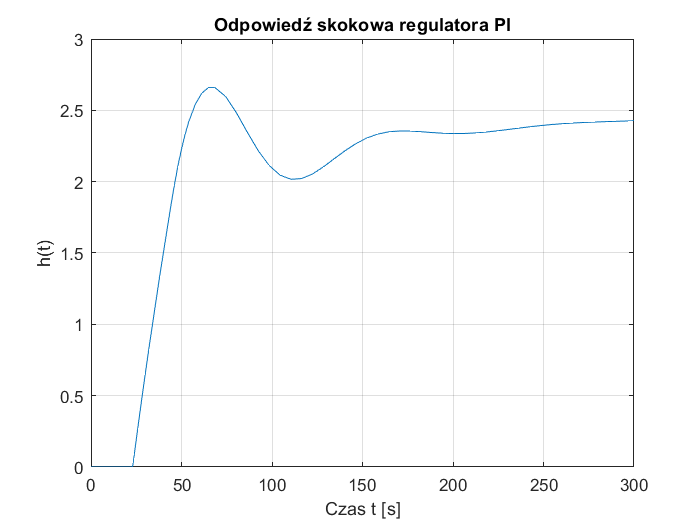


kreg = 0.45 * kkryt;
Ti = 1/(0.85 * Tosc);
Td = 0;
out = sim("model.slx");
plot(out.y.time, out.y.signals.values)
title("Odpowiedź skokowa regulatora PI")
xlabel("Czas t [s]")
ylabel("h(t)")
grid on

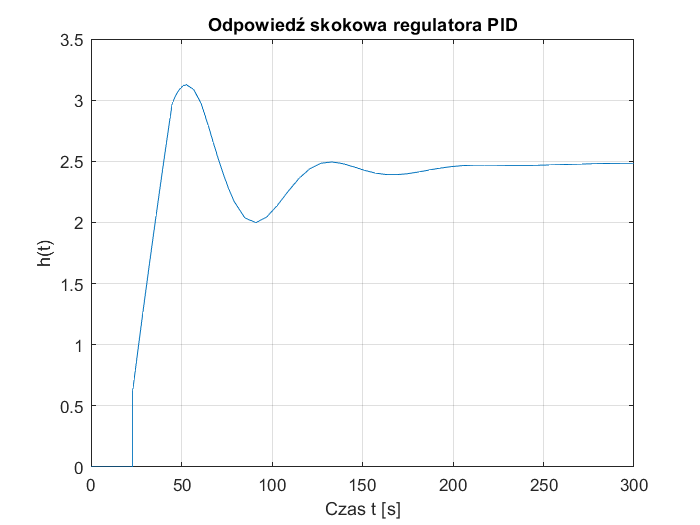


kreg = 0.6 * kkryt;
Ti = 1/(0.5 * Tosc);
Td = 0.12 * Tosc;
out = sim("model.slx");
plot(out.y.time, out.y.signals.values)
title("Odpowiedź skokowa regulatora PID")
xlabel("Czas t [s]")
ylabel("h(t)")
grid on

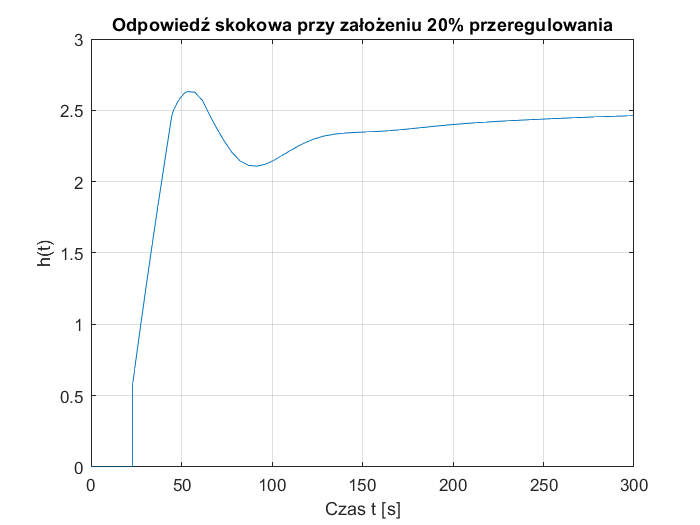

k = 1.18;
tau = 22;
T = 45;

kreg = (0.95 * T)/(k * tau);
Ti = 1/(2.4 * tau);
Td = 0.4 * tau;
out = sim("model.slx");
plot(out.y.time, out.y.signals.values)
title("Odpowiedź skokowa przy założeniu 20% przeregulowania")
xlabel("Czas t [s]")
ylabel("h(t)")
grid on

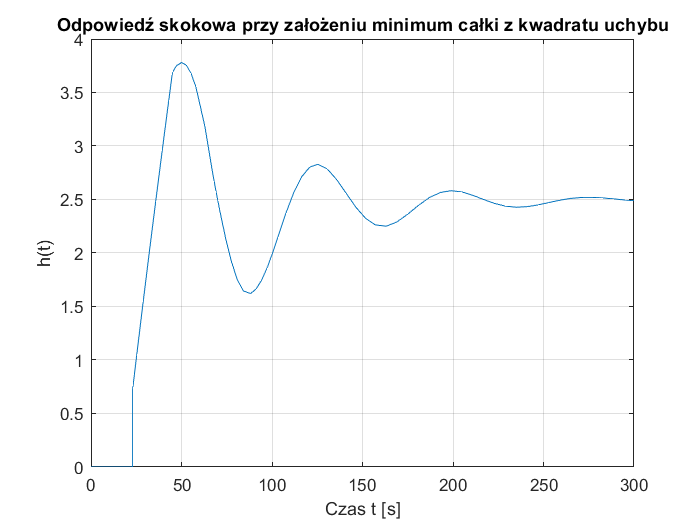


kreg = (1.4 * T)/(k * tau);
Ti = 1/(1.3 * tau);
Td = 0.5 * tau;
out = sim("model.slx");
plot(out.y.time, out.y.signals.values)
title("Odpowiedź skokowa przy założeniu minimum całki z kwadratu uchybu")
xlabel("Czas t [s]")
ylabel("h(t)")
grid on